clear
close all
clc
addpath 'C:\GitHub\MatLab\Resources'
addpath 'C:\GitHub\MatLab\stability-tests\'

## Sections

crossSectionsSet.import = importdata("sectionsSet.mat");
crossSectionsSet.A = table2array(crossSectionsSet.import.L(:,"A"));
crossSectionsSet.Iy = table2array(crossSectionsSet.import.L(:,"I_y"));
crossSectionsSet.Iz = table2array(crossSectionsSet.import.L(:,"I_z"));
crossSectionsSet.Ip = table2array(crossSectionsSet.import.L(:,"I_t"));

sections.id = [10;10];

for i = 1:size(sections.id,1)
    sections.A(i,1)  = crossSectionsSet.A(sections.id(1));
    sections.Iy(i,1) = crossSectionsSet.Iy(sections.id(1));
    sections.Iz(i,1) = crossSectionsSet.Iz(sections.id(1));
    sections.Ix(i,1) = crossSectionsSet.Ip(sections.id(1));
    sections.E(i,1)  = 210*10^9;
    sections.v(i,1)  = 0.3;
end

ndisc = 5

ndisc = 5

## Nodes

nodes.x = [0;5;10];                            % x coordinates of nodes
nodes.y = [0;5;10];                              % y coordinates of nodes
nodes.z = [0;5;0];
nnodes = numel(nodes.x); 

## Supports

kinematic.x.nodes = [1;3];              % node indices with restricted x-direction displacements
kinematic.y.nodes = [1;3];              % node indices with restricted y-direction displacements
kinematic.z.nodes = [1;3];              % node indices with restricted z-direction displacements
kinematic.rx.nodes = [1;3];             % node indices with restricted x-direction displacements
kinematic.ry.nodes = [1;3];             % node indices with restricted y-direction displacements
kinematic.rz.nodes = [1;3];             % node indices with restricted z-direction displacements

nodes.dofs = true(nnodes,6);                 % no kinematic boundary conditions
nodes.dofs(kinematic.x.nodes,1) = false;     % mark prevented movement in x-direction
nodes.dofs(kinematic.y.nodes,2) = false;     % mark prevented movement in y-direction
nodes.dofs(kinematic.z.nodes,3) = false;     % mark prevented movement in z-direction
nodes.dofs(kinematic.rx.nodes,4) = false;    % mark prevented movement in x-direction
nodes.dofs(kinematic.ry.nodes,5) = false;    % mark prevented movement in y-direction
nodes.dofs(kinematic.rz.nodes,6) = false;    % mark prevented movement in z-direction

## Beams

beams.nodesHead = [1;2];    % elements starting nodes
beams.nodesEnd =  [2;3];    % elements ending nodes
nr = numel(beams.nodesHead);

### Beams sections

beams.disc      = ones(nr,1)*ndisc;
beams.sections = [1;2];

beams.angles = [0;0];
ng = max(max(beams.sections));
plot3([nodes.x(beams.nodesHead) nodes.x(beams.nodesEnd)]', ...
     [nodes.y(beams.nodesHead) nodes.y(beams.nodesEnd)]', ...
     [nodes.z(beams.nodesHead) nodes.z(beams.nodesEnd)]', ...
     'k','LineWidth',1);
hold on;
scatter3(nodes.x, nodes.y, nodes.z, 'black', 'filled', 'o');
axis equal;
xlim([min(nodes.x)-1,max(nodes.x)+1]);  % to avoid tight limits
ylim([min(nodes.y)-1,max(nodes.y)+1]);  % to avoid tight limits
zlim([min(nodes.z)-1,max(nodes.z)+1]);  % to avoid tight limits
grid on


## Loads

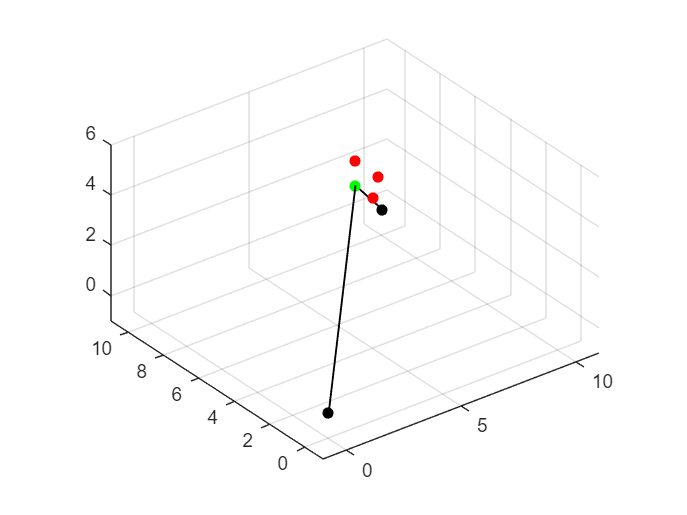

loads.y.nodes = [2];             % node indices with x-direction forces
loads.y.value = [1];             % magnitude of the x-direction forces
loads.x.nodes = [2];             % node indices with y-direction forces
loads.x.value = [-1];             % magnitude of the y-direction forces 
loads.z.nodes = [2];             % node indices with y-direction forces
loads.z.value = [-1];             % magnitude of the y-direction forces 

loads.rx.nodes = [];          % node indices with x-direction forces
loads.rx.value = [];          % magnitude of the x-direction forces
loads.ry.nodes = [];          % node indices with y-direction forces
loads.ry.value = [];          % magnitude of the y-direction forces 
loads.rz.nodes = [];          % node indices with z-direction forces
loads.rz.value = []; 
loadsVisibility = true;
if loadsVisibility
    scatter3(nodes.x(loads.x.nodes)-loads.x.value, nodes.y(loads.x.nodes), nodes.z(loads.x.nodes), 'red', 'filled', 'o');
    scatter3(nodes.x(loads.x.nodes), nodes.y(loads.x.nodes), nodes.z(loads.x.nodes), 'green', 'filled', 'o');
    scatter3(nodes.x(loads.y.nodes), nodes.y(loads.y.nodes)-loads.y.value, nodes.z(loads.y.nodes), 'red', 'filled', 'o');
    scatter3(nodes.x(loads.y.nodes), nodes.y(loads.y.nodes), nodes.z(loads.y.nodes), 'green', 'filled', 'o');
    scatter3(nodes.x(loads.z.nodes), nodes.y(loads.z.nodes), nodes.z(loads.z.nodes)-loads.z.value, 'red', 'filled', 'o');
    scatter3(nodes.x(loads.z.nodes), nodes.y(loads.z.nodes), nodes.z(loads.z.nodes), 'green', 'filled', 'o');
end
hold off;

## Force vector

forceVector = sparse([loads.x.nodes*6-5; loads.y.nodes*6-4; loads.z.nodes*6-3;loads.rx.nodes*3-2; loads.ry.nodes*3-1; loads.rz.nodes*3], ...
                     1, ...
                     [loads.x.value; loads.y.value; loads.z.value;loads.rx.value; loads.ry.value; loads.rz.value], ...
                     nnodes*6, 1);
f = forceVector(reshape(reshape(nodes.dofs.',[],1).', 1, [])');
% f = full(f)

## FEM

nodes.ndofs = sum(sum(nodes.dofs));
nodes.nnodes    = nnodes;

beams.nbeams  = nr;
beams.vertex = beamVertexFn(beams,nodes);
beams.codeNumbers = codeNumbersFn(beams,nodes);
beams.XY = XYtoBeamsFn(beams);

elements = discretizationBeamsFn(beams,nodes);
elements.XY = XYtoElementFn(beams);
elements.sections = sectionToElementFn(sections,beams);
elements.ndofs = max(max(elements.codeNumbers));



%------------------------------------------------------------------------
%   Linear analysis
%------------------------------------------------------------------------
endForces.global = sparse(elements.ndofs,1);
endForces.global(1:max(max(beams.codeNumbers))) = f;

transformationMatrix = transformationMatrixFn(elements);

stiffnesMatrix = stiffnessMatrixFn(elements,transformationMatrix);

[endForces.local, displ] = EndForcesFn(stiffnesMatrix,endForces,transformationMatrix,elements);
%------------------------------------------------------------------------
%   Non-linear analysis
%------------------------------------------------------------------------
geometricMatrix = geometricMatrixFnV2(elements,transformationMatrix,endForces);
% geometricMatrix = geometricMatrixOOFEMFn(elements,transformationMatrix,endForces);

% [geometricMatrix.local,geometricMatrix.global] = geometricMoofemFn(elements.sections.A,...
%          elements.sections.Ix,transformationMatrix.matrices,transformationMatrix.lengths,endForces.local,elements.ndofs,...
%          elements.nelement,elements.codeNumbers,12);

volume = sum(elements.sections.A .* transformationMatrix.lengths);
% 
Results = criticalLoadFn(stiffnesMatrix,geometricMatrix);
% 
[sortedValues,sortedVectors]= sortValuesVectorFn(Results.values,Results.vectors);

oofem = struct with fields:
          nodes: [11×3 double]
          beams: [10×2 double]
        refNode: [10×3 double]
       sections: [1×1 struct]
          loads: [1×1 struct]
      kinematic: [1×1 struct]
    sectionProp: [1×1 struct]


_______________________________________________________
In ErrorCheckingExportModule::initializeFrom (/home/hexic/oofem/src/oofemlib/errorcheckingexportmodule.C:725)
_______________________________________________________□
____________________________________________________
  ____  ____  __________  ___ 
 / __ \/ __ \/ __/ __/  |/  /___  _______
/ /_/ / /_/ / _// _// /|_/ // _ \/ __/ _ `
\____/\____/_/ /___/_/  /_(_)___/_/  \_, / 
Copyright (C) 1994-2024 Borek Patzak /__/
____________________________________________________
OctreeLocalizer: init
Spatial localizer init done
Assembling stiffness matrix
Assembling load
Solving linear static problem
Assembling stiffness  matrix
Assembling  initial stress matrix
Solving ...
SubspaceIteration :: solveYourselfAt: Convergence reached for RTOL=   0.000000010000000
Checking rules...
Checking rules...
Checking rules...
Checking rules...
Checking rules...
Checking rules...
Checking rules...


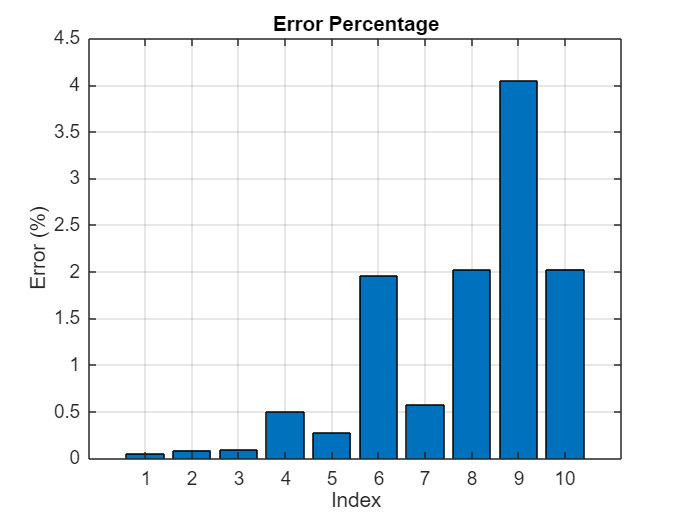

[h,errors] = oofemTestFn(nodes, beams, loads, kinematic, sections, sortedValues);

errors

errors =     0.0460
    0.0870
    0.0887
    0.4961
    0.2712
    1.9564
    0.5764
    2.0238
    4.0515
    2.0264
